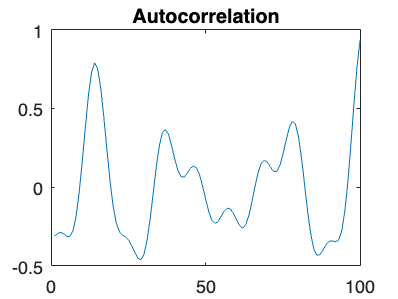

audio_signal = audioread('sax.wav');

% Parameters
frame_length = 512;    % Length of each frame
overlap = frame_length * 0.75;  % Overlap between frames
pre_emphasis_coeff = 0.96;  % Pre-emphasis filter coefficient
threshold = 400;  % Adjust this threshold based on your data
sampling_rate = 8000;


% Preprocessing
num_samples = length(audio_signal);
num_frames = floor((num_samples - overlap) / (frame_length - overlap));

% Initialize arrays to store non-silent frames
non_silent_frames = zeros(frame_length, num_frames);

% Apply preprocessing steps frame by frame
for i = 1:num_frames
    % Extract a frame
    start_sample = (i - 1) * (frame_length - overlap) + 1;
    end_sample = start_sample + frame_length - 1;
    frame = audio_signal(start_sample:end_sample);
    
    % Apply pre-emphasis filter
    pre_emphasized_frame = frame - pre_emphasis_coeff * [0, frame(1:end-1)];
    
    % Apply Hamming window
    hamming_window = 0.54 - 0.46 * cos(2 * pi * (0:frame_length-1) / (frame_length - 1));
    hamming_windowed_frame = pre_emphasized_frame .* hamming_window;
    
    % Calculate frame energy as the sum of squared samples
    frame_energy = sum(hamming_windowed_frame.^2);
    
    % Check if the frame is non-silent based on the threshold
    if frame_energy > threshold
        non_silent_frames(:, i) = hamming_windowed_frame;
        
    end
end
%plot(hamming_windowed_frame)
%xlim([0,100])

pitch_frequency = extract_pitch_feature(hamming_windowed_frame, sampling_rate);